%1. least squares

TS = [5 20 18 40 33 54 70 60 78];
T = [10 15 20 25 40 50 55 60 75];
b = TS';
deltaT = T(1):0.1:T(end);

A1 = [ones(length(TS), 1) T'];
[x11, x21] = LSsolver(A1, b);
lin_func = x11+x21*deltaT;
e1 = b-A1*[x11; x21];
e1_mag = sum(e1.^2)

e1_mag = 476.6712


A2 = [ones(length(TS), 1) (T').^2];
[x12, x22] = LSsolver(A2, b);
quad_func = x12+x22*deltaT.^2;
e2 = b-A2*[x12; x22];
e2_mag = sum(e2.^2)

e2_mag = 789.6823


A3 = [ones(length(TS), 1) (T').^0.5];
[x13, x23] = LSsolver(A3, b);
sqrt_func = x13+x23*sqrt(deltaT);
e3 = b-A3*[x13; x23];
e3_mag = sum(e3.^2)

e3_mag = 456.9278


TS_32 = x13+x23*sqrt(32)

TS_32 = 38.0796

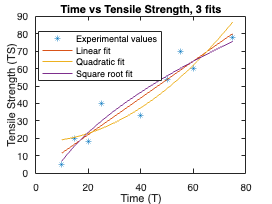


figure
plot(T, TS, "*")
hold on
plot(deltaT, lin_func)
plot(deltaT, quad_func)
plot(deltaT, sqrt_func)
xlabel("Time (T)")
ylabel("Tensile Strength (TS)")
legend("Experimental values", "Linear fit", "Quadratic fit", "Square root fit", "location", "best")
title("Time vs Tensile Strength, 3 fits")


%2. integrals
res_A = 50.667;
n = 109;
dx = 2/n;
x = linspace(0, 2, n+1)

x =          0    0.0183    0.0367    0.0550    0.0734    0.0917    0.1101    0.1284    0.1468    0.1651    0.1835    0.2018    0.2202    0.2385    0.2569    0.2752    0.2936    0.3119    0.3303    0.3486    0.3670    0.3853    0.4037    0.4220    0.4404    0.4587    0.4771    0.4954    0.5138    0.5321    0.5505    0.5688    0.5872    0.6055    0.6239    0.6422    0.6606    0.6789    0.6972    0.7156    0.7339    0.7523    0.7706    0.7890    0.8073    0.8257    0.8440    0.8624    0.8807    0.8991


F = 4*x.^5 + 3*x.^3 - 2;
res_L = sum(F(1:end-1)*dx)

res_L = 49.2822

res_T = sum((F(1:end-1)+F(2:end))*dx/2)

res_T = 50.6767


mres_l = nan(1, 91);
mres_t = nan(1, 91);

for n = 10:100
    x = linspace(0, 2, n+1);
    dx = 2/n;
    F = 4*x.^5 + 3*x.^3 - 2;
    res_L = sum(F(1:end-1)*dx);
    res_T = sum((F(1:end-1)+F(2:end))*dx/2);
    mres_l(n-9) = res_L;
    mres_t(n-9) = res_T;
end

for n = 10:200
    x = linspace(0, 2, n+1);
    dx = 2/n;
    F = 4*x.^5 + 3*x.^3 - 2;
    res_T = sum((F(1:end-1)+F(2:end))/2*dx);
    if abs(res_T-res_A) <= 0.01
        break
    end
end

n_min = n

n_min = 108


x = linspace(0, 2, n_min+1);
dx = 2/n_min;
F = 4*x.^5 + 3*x.^3 - 2;
res_Lmin = sum(F(1:end-1)*dx);
abs_error = abs(res_Lmin-res_A)

abs_error = 1.3976

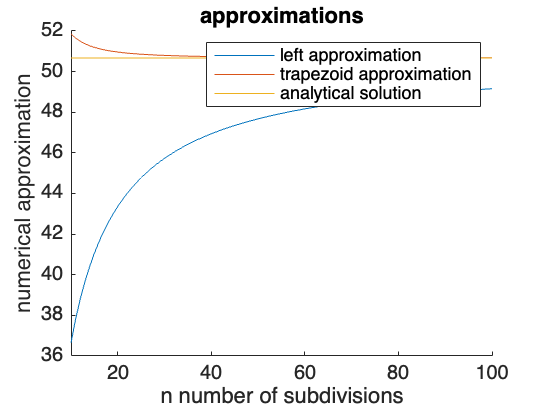


figure
hold on
plot(10:100, mres_l)
plot(10:100, mres_t)
plot([10 100], [res_A res_A])
xlim([10, 100])
title("approximations")
xlabel("n number of subdivisions")
ylabel("numerical approximation")
legend("left approximation", "trapezoid approximation", "analytical solution")

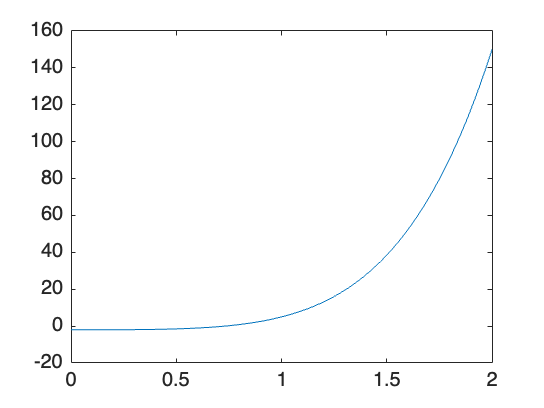


x = linspace(0, 2, 2/0.01+1);
F = 4*x.^5 + 3*x.^3 - 2;

figure
plot(x, F)

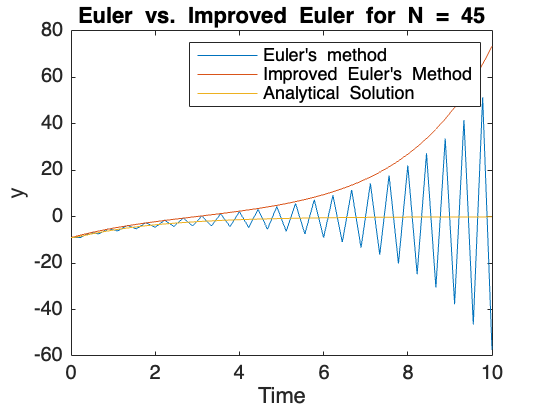

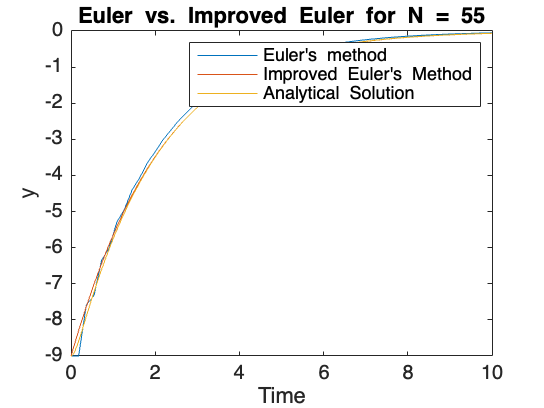

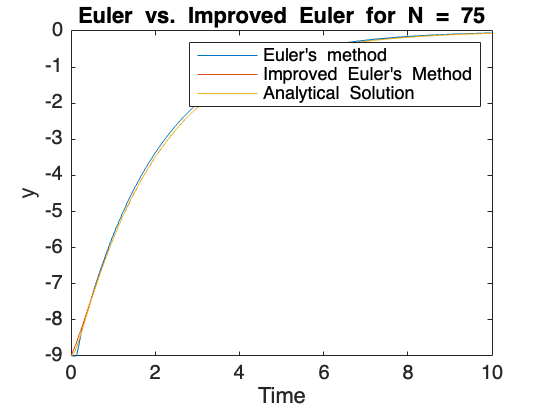

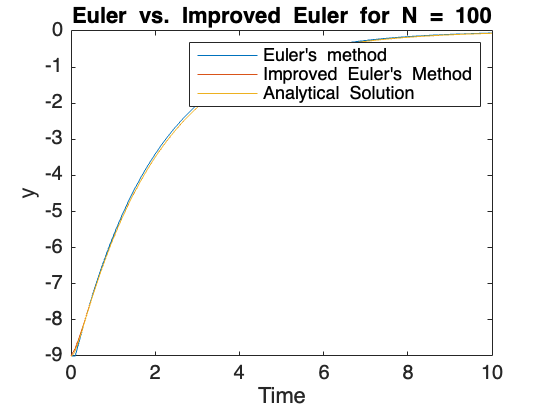

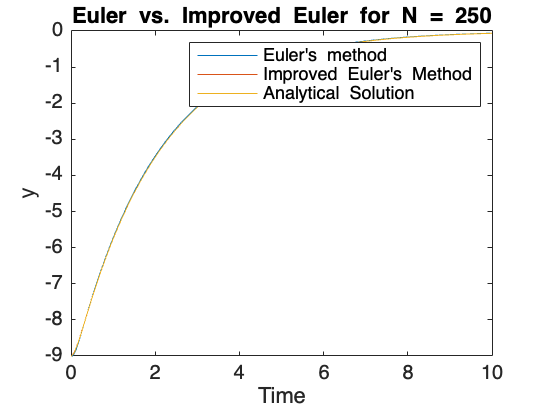


%3. Euler's method
A = [0 1; -19/4 -10];
Z_0 = [-9 0];
N_arr = [45 55 75 100 250];
t = [0 10];
t_a = 0:0.01:10;
y_a = -19/2*exp(-t_a/2)+1/2*exp(-19/2*t_a);

i = 1;
for N = N_arr
    t_bounds = linspace(t(1), t(2), N+1);
    y_EM = EM1(A, -9, 0, t, N);
    y_IEM = IEM1(A, -9, 0, t, N);
    figure()
    plot(t_bounds, y_EM)
    hold on
    plot(t_bounds, y_IEM)
    hold on
    plot(t_a, y_a)
    title(sprintf('Euler  vs.  Improved  Euler  for  N  =  %d',  N)) 
    xlabel('Time') 
    ylabel('y') 
    legend("Euler's  method",  "Improved  Euler's  Method",  "Analytical  Solution")
    i = i+1;
end

function [x1, x2] = LSsolver(A, b)
    x = A'*A\(A'*b);
    x1 = x(1);
    x2 = x(2);
end

function y = EM1(A, y0, yprime0, t_bounds, N)
    delta_t = (t_bounds(2)-t_bounds(1))/N;
    Z = zeros(2, N+1);
    Z(:, 1) = [y0; yprime0];

    for n = 1:N
        Z(:, n+1) = Z(:, n)+delta_t*A*Z(:, n);
    end
    y = Z(1, :);
end

function y = IEM1(A, y0, yprime0, t_bounds, N)
    delta_t = (t_bounds(2)-t_bounds(1))/N;
    Z = zeros(2, N+1);
    Z(:, 1) = [y0; yprime0];

    for n = 1:N
        Z_R = Z(:,n) + delta_t*A*Z(:,n);
        Z(:,n+1) = Z(:,n)+delta_t/2*A*(Z(:,n)+Z_R);
    end
    y = Z(1,:);
end
